# MATLAB & Simulink workshop

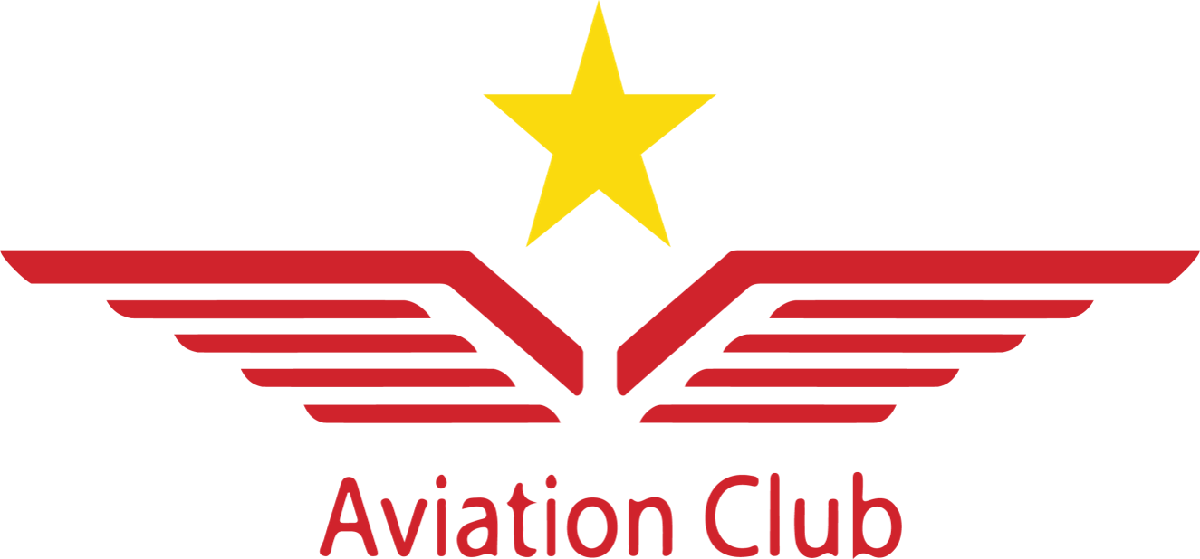

## Session 4: Data Visulization

Before we start any script

clear
clc
close all %we would see why in today's session 

### Part 1: Tips & Tricks

#### Useful built-in functions

size() and length()

x=1:9

x =      1     2     3     4     5     6     7     8     9


y=[x;x]

y =      1     2     3     4     5     6     7     8     9
     1     2     3     4     5     6     7     8     9


size(x)

ans =      1     9


length(x)

ans = 9

size(y)

ans =      2     9


length(y)

ans = 9

sum()

x=1:9

x =      1     2     3     4     5     6     7     8     9


y=[x;x]

y =      1     2     3     4     5     6     7     8     9
     1     2     3     4     5     6     7     8     9


sum(x)

ans = 45

sum(y)

ans =      2     4     6     8    10    12    14    16    18


sum(y,1)

ans =      2     4     6     8    10    12    14    16    18


sum(y,2)

ans =     45
    45


sum(y,"all")

ans = 90

any() and all()

x=1:9

x =      1     2     3     4     5     6     7     8     9


y=0:9

y =      0     1     2     3     4     5     6     7     8     9


any(x)

ans = logical
   1


all(x)

ans = logical
   1


any(y)

ans = logical
   1


all(y)

ans = logical
   0


linspace()

x=1:1:10  %controls steps  

x =      1     2     3     4     5     6     7     8     9    10


y=linspace(1,10,50)  %controls number of elements

y =     1.0000    1.1837    1.3673    1.5510    1.7347    1.9184    2.1020    2.2857    2.4694    2.6531    2.8367    3.0204    3.2041    3.3878    3.5714    3.7551    3.9388    4.1224    4.3061    4.4898    4.6735    4.8571    5.0408    5.2245    5.4082    5.5918    5.7755    5.9592    6.1429    6.3265    6.5102    6.6939    6.8776    7.0612    7.2449    7.4286    7.6122    7.7959    7.9796    8.1633    8.3469    8.5306    8.7143    8.8980    9.0816    9.2653    9.4490    9.6327    9.8163   10.0000


isscalar()

x=1

x = 1

y=1:5

y =      1     2     3     4     5


isscalar(x)

ans = logical
   1


isscalar(y)

ans = logical
   0


Mathematical expressions and functions:

- sqrt()

- abs()

- sin() , cos(), tan()

- sind(), cosd(), tand()

- asin(), acos(), atan()

- exp()

- log(), log10()

- pi

- e

sqrt(4)

ans = 2

abs([-1 0 5])

ans =      1     0     5


sin(90)

ans = 0.8940

sind(90)

ans = 1

asin(1)

ans = 1.5708

exp(1)

ans = 2.7183

log(exp(2))

ans = 2

pi

ans = 3.1416

1e5

ans = 100000

#### General ideas

You can use help with your own functions

help myfun

 this is explanation of my function it basically does nothing and I am ok
 with that, you can use it like that a=myfun(b) and absolutely nothing will
 happen so you don't have to use it all, but it is nice that I can write my
 own function :D



Let's revise working with scripts and the debugging tool 

session_4

samples =     0.8147    0.9058    0.1270    0.9134    0.6324    0.0975    0.2785    0.5469    0.9575    0.9649    0.1576    0.9706    0.9572    0.4854    0.8003    0.1419    0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.8235    0.6948    0.3171    0.9502    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547


samplesnormal =    -1.7947    0.8404   -0.8880    0.1001   -0.5445    0.3035   -0.6003    0.4900    0.7394    1.7119   -0.1941   -2.1384   -0.8396    1.3546   -1.0722    0.9610    0.1240    1.4367   -1.9609   -0.1977   -1.2078    2.9080    0.8252    1.3790   -1.0582   -0.4686   -0.2725    1.0984   -0.2779    0.7015   -2.0518   -0.3538   -0.8236   -1.5771    0.5080    0.2820    0.0335   -1.3337    1.1275    0.3502   -0.2991    0.0229   -0.2620   -1.7502   -0.2857   -0.8314   -0.9792   -1.1564   -0.5336   -2.0026


### Part 2: 2D-Plotting

Let's start by plotting a simple line 

x=linspace(0,4*pi,10)

x =          0    1.3963    2.7925    4.1888    5.5851    6.9813    8.3776    9.7738   11.1701   12.5664


y=x

y =          0    1.3963    2.7925    4.1888    5.5851    6.9813    8.3776    9.7738   11.1701   12.5664


plot(x,y)

Let's make slightely more advanced plot with 10 points

x=linspace(0,4*pi,10)

x =          0    1.3963    2.7925    4.1888    5.5851    6.9813    8.3776    9.7738   11.1701   12.5664


y=sin(x)

y =          0    0.9848    0.3420   -0.8660   -0.6428    0.6428    0.8660   -0.3420   -0.9848   -0.0000


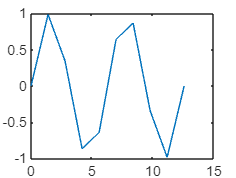

plot(x,y)

Try changing the number of points to see what happens

x=linspace(0,4*pi,100)

x =          0    0.1269    0.2539    0.3808    0.5077    0.6347    0.7616    0.8885    1.0155    1.1424    1.2693    1.3963    1.5232    1.6501    1.7771    1.9040    2.0309    2.1579    2.2848    2.4117    2.5387    2.6656    2.7925    2.9195    3.0464    3.1733    3.3003    3.4272    3.5541    3.6811    3.8080    3.9349    4.0619    4.1888    4.3157    4.4427    4.5696    4.6965    4.8235    4.9504    5.0773    5.2043    5.3312    5.4581    5.5851    5.7120    5.8389    5.9659    6.0928    6.2197


y=sin(x)

y =          0    0.1266    0.2511    0.3717    0.4862    0.5929    0.6901    0.7761    0.8497    0.9096    0.9549    0.9848    0.9989    0.9969    0.9788    0.9450    0.8960    0.8326    0.7557    0.6668    0.5671    0.4582    0.3420    0.2203    0.0951   -0.0317   -0.1580   -0.2817   -0.4009   -0.5137   -0.6182   -0.7127   -0.7958   -0.8660   -0.9224   -0.9638   -0.9898   -0.9999   -0.9938   -0.9718   -0.9341   -0.8815   -0.8146   -0.7346   -0.6428   -0.5406   -0.4298   -0.3120   -0.1893   -0.0634


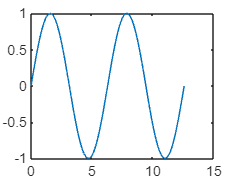

plot(x,y)

Try plotting this yourself


$$x=16\;\sin^3 \left(t\right)$$



$$y=13\;\cos \left(t\right)-5\;\cos \left(2t\right)-2\;\cos \left(3t\right)-\cos \left(4t\right)$$


Let's explore the plot command more

help plot

Try plot line/marker options

plot(x,y,'r')

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

LineWidth and MarkerSize arguments

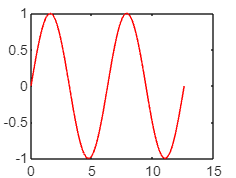

plot(x,y,'or-','LineWidth',2,'MarkerSize',8,'MarkerEdgeColor','g')

You can control or add all of these of a plot

- axes limits

- axes label

- plot title

- grid

- text

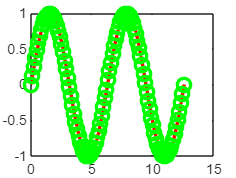

plot(x,y)

xlabel('time (seconds)')
ylabel('Speed (m/s)')
title('Speed-time graph for my project')
%axis([0,4*pi,-1,1])
axis equal
grid on
text(0.05,-0.5,'this is MY GRAPH','Color','k','FontSize',10)

You can add multiple plots on the same figure

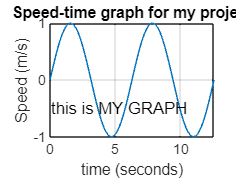

close all
x=linspace(0,4*pi,100);
y1=sin(x);

y2=sin(2*x);
plot(x,y1)
hold on
plot(x,y2)

Add legend to illustrate which signal is which

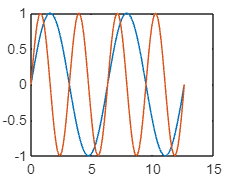

close all
x=linspace(0,4*pi,100);
y1=sin(x);
y2=sin(2*x);
plot(x,y1)

hold on
plot(x,y2)
legend('unity frequency','double frequency','Location','northeast')
hold off

Figures and subplots (go to the normal script)

session_4

Other types of 2D-plots

- histogram

- plotyy

- semilog

- pie

- scatter

close all
samples=rand(1,100)
histogram(samples,10)

### Part3: 3D-Plotting

Basic plotting

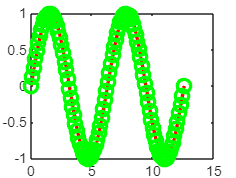

x=linspace(0,8*pi,100);
y=sin(x);

z=cos(x);
plot3(x,y,z)

Changing the view

x=linspace(0,8*pi,100);

samples =     0.8116    0.5328    0.3507    0.9390    0.8759    0.5502    0.6225    0.5870    0.2077    0.3012    0.4709    0.2305    0.8443    0.1948    0.2259    0.1707    0.2277    0.4357    0.3111    0.9234    0.4302    0.1848    0.9049    0.9797    0.4389    0.1111    0.2581    0.4087    0.5949    0.2622    0.6028    0.7112    0.2217    0.1174    0.2967    0.3188    0.4242    0.5079    0.0855    0.2625    0.8010    0.0292    0.9289    0.7303    0.4886    0.5785    0.2373    0.4588    0.9631    0.5468


samplesnormal =    -2.1924   -2.3193    0.0799   -0.9485    0.4115    0.6770    0.8577   -0.6912    0.4494    0.1006    0.8261    0.5362    0.8979   -0.1319   -0.1472    1.0078   -2.1237   -0.5046   -1.2706   -0.3826    0.6487    0.8257   -1.0149   -0.4711    0.1370   -0.2919    0.3018    0.3999   -0.9300   -0.1768   -2.1321    1.1454   -0.6291   -1.2038   -0.2539   -1.4286   -0.0209   -0.5607    2.1778    1.1385   -2.4969    0.4413   -1.3981   -0.2551    0.1644    0.7477   -0.2730    1.5763   -0.4809    0.3275


y=sin(x);
z=cos(x);
plot3(x,y,z)
view([10 20])

#### Other 3D-plotting commands

patch()

x=[1 0 0]

samples =     0.4709    0.6959    0.6999    0.6385    0.0336    0.0688    0.3196    0.5309    0.6544    0.4076    0.8200    0.7184    0.9686    0.5313    0.3251    0.1056    0.6110    0.7788    0.4235    0.0908    0.2665    0.1537    0.2810    0.4401    0.5271    0.4574    0.8754    0.5181    0.9436    0.6377    0.9577    0.2407    0.6761    0.2891    0.6718    0.6951    0.0680    0.2548    0.2240    0.6678    0.8444    0.3445    0.7805    0.6753    0.0067    0.6022    0.3868    0.9160    0.0012    0.4624


y=[0 1 0]
z=[0 0 1]
patch(x,y,z,'k')

surf() and mesh()

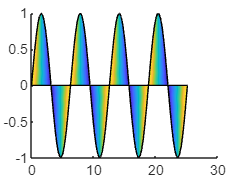

close all
figure
x=linspace(0,4*pi,100);
y=linspace(0,4*pi,100);
[X,Y]=meshgrid(x,y);
z=cos(X).*Y;
mesh(X,Y,z)
colorbar;
figure
surf(X,Y,z)
shading interp

colorbar;

###  Part4: Animations

Basic animation (on normal script)

x =      1     0     0


y =      0     1     0


z =      0     0     1


session_4